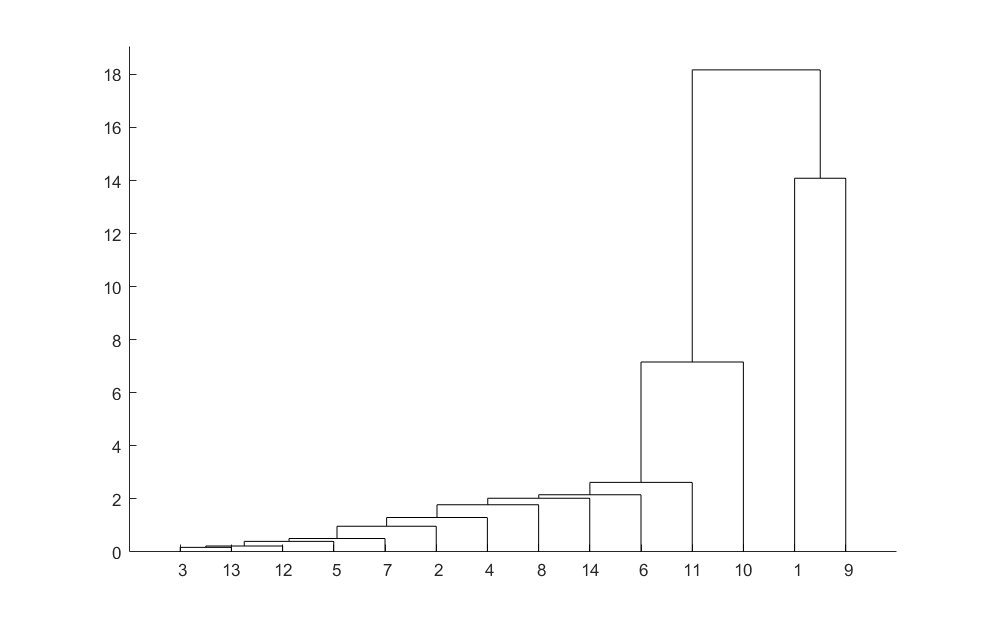

划分成4类的结果如下:
第1类的有:氧化钡(BaO),
第2类的有:氧化钠(Na2O),氧化钾(K2O),氧化钙(CaO),氧化镁(MgO),氧化铝(Al2O3),氧化铁(Fe2O3),氧化铜(CuO),五氧化二磷(P2O5),氧化锶(SrO),氧化锡(SnO2),二氧化硫(SO2),
第3类的有:二氧化硅(SiO2),
第4类的有:氧化铅(PbO),


%先R型聚类分析
clear;clc

table1=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","铅钡无风化");
table2=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","铅钡风化");

table3=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","高钾无风化");
table4=readtable("分组.xlsx","VariableNamingRule","preserve","Sheet","高钾风化");
varName=table1.Properties.VariableNames(2:end);
temp=[table1;table2];
draw(table2array(temp(:,2:end))',varName)

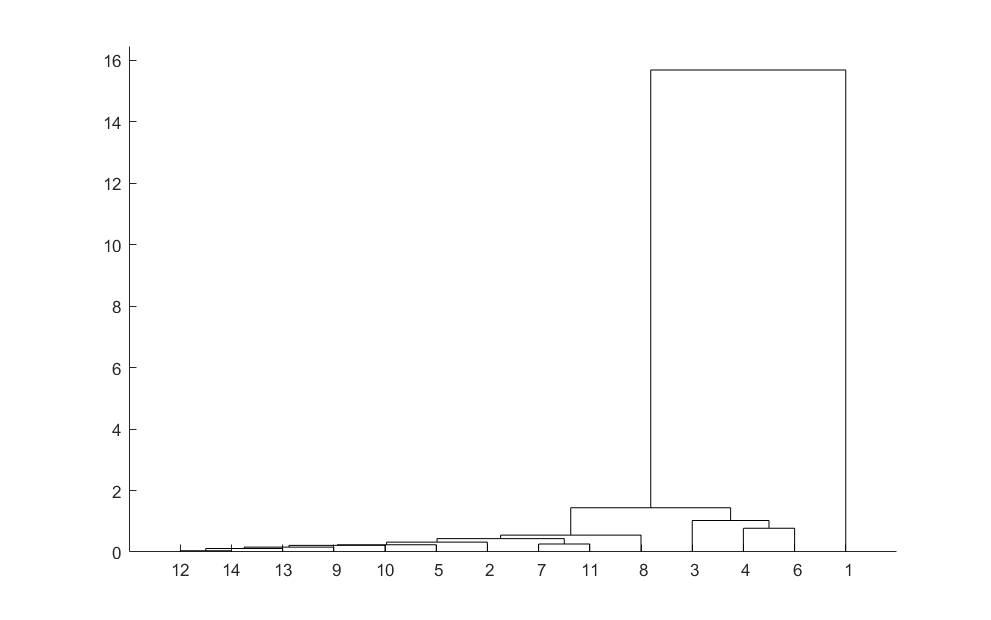

划分成4类的结果如下:
第1类的有:氧化钾(K2O),
第2类的有:氧化钙(CaO),氧化铝(Al2O3),
第3类的有:氧化钠(Na2O),氧化镁(MgO),氧化铁(Fe2O3),氧化铜(CuO),氧化铅(PbO),氧化钡(BaO),五氧化二磷(P2O5),氧化锶(SrO),氧化锡(SnO2),二氧化硫(SO2),
第4类的有:二氧化硅(SiO2),


temp=[table3;table4];
draw(table2array(temp(:,2:end))',varName)

fprintf("\n*********铅钡划分子类，分为四类************\n")


*********铅钡划分子类，分为四类************


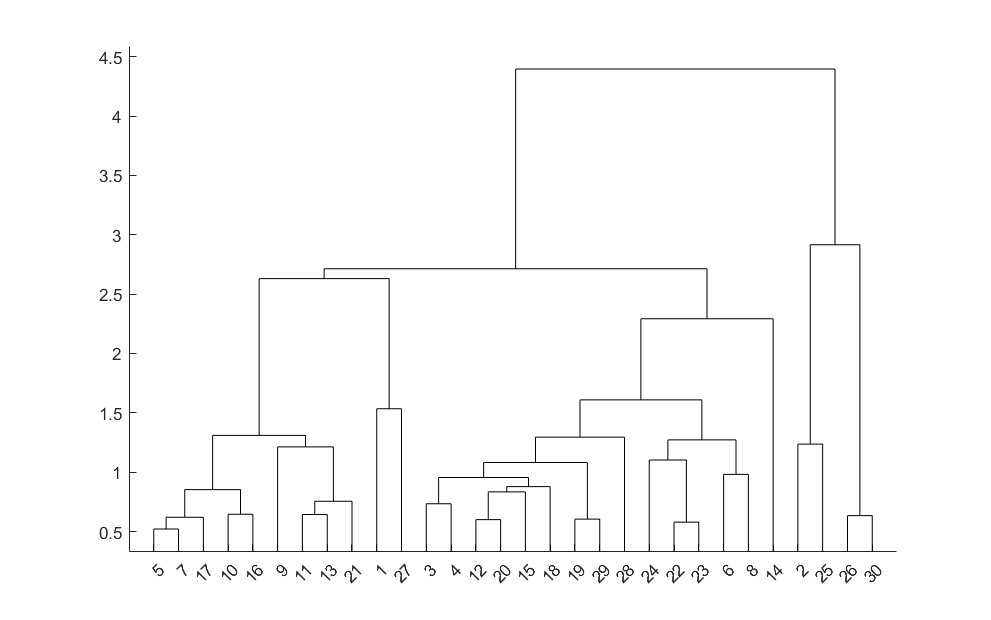

划分成4类的结果如下:
第1类的有:30部位1,30部位2,02,19,34,36,38,39,40,41,43部位1,43部位2,49,50,51部位1,51部位2,52,54,54严重风化点,56,57,58,
第2类的有:20,31,32,33,35,37,45,46,47,55,23未风化点,25未风化点,28未风化点,29未风化点,42未风化点1,42未风化点2,44未风化点,49未风化点,50未风化点,53未风化点,11,48,
第3类的有:08严重风化点,26严重风化点,
第4类的有:24,08,26,


% 铅钡划分子类，分为四类
temp1=[table1;table2];
member=temp1.("文物采样点");
%包含硅元素，依照金属元素Ba、Pb\含量进行聚类
selectData=[1 8 9 10];
data=table2array(temp1(:,2:end));
draw(data(:,selectData),member)

划分成4类的结果如下:
第1类的有:30部位1,30部位2,02,19,34,36,38,39,40,41,43部位1,43部位2,49,50,51部位1,51部位2,52,54,54严重风化点,56,57,58,
第2类的有:20,31,32,33,35,37,45,46,47,55,23未风化点,25未风化点,28未风化点,29未风化点,42未风化点1,42未风化点2,44未风化点,49未风化点,50未风化点,53未风化点,11,48,
第3类的有:08严重风化点,26严重风化点,
第4类的有:24,08,26,


% 利用对指定项增加N(0,1)随机数进行扰动，检验敏感性
for i=size(data,1)
    data=data(:,selectData)+normrnd(0,1,[1 size(selectData,2)]);
end
draw(data,member)

%结果显示敏感性低，较为稳定

fprintf("\n*********高钾划分子类，分为四类************\n")


*********高钾划分子类，分为四类************


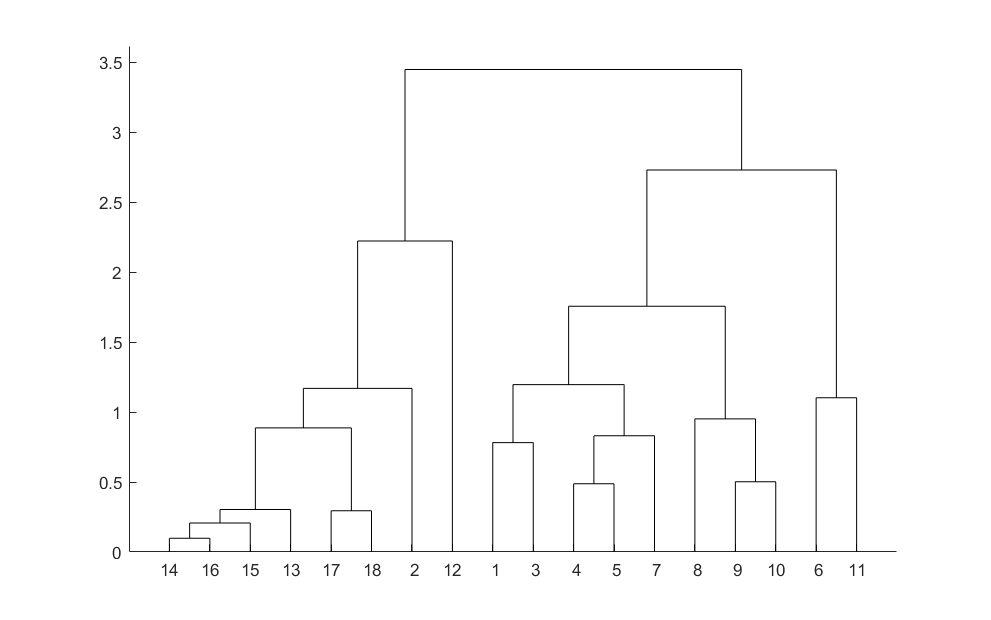

划分成4类的结果如下:
第1类的有:21,
第2类的有:03部位1,07,09,10,12,22,27,
第3类的有:06部位1,18,
第4类的有:01,03部位2,04,05,06部位2,13,14,16,


% 高钾划分子类，分为四类
temp2=[table3;table4];
member=temp2.("文物采样点");
%包含硅元素，依照活跃元素K、Ca、Mg含量进行聚类
selectData=[1 3 4 5];
data=table2array(temp2(:,2:end));
draw(data(:,selectData),member)

划分成4类的结果如下:
第1类的有:21,
第2类的有:03部位1,07,09,10,12,22,27,
第3类的有:06部位1,18,
第4类的有:01,03部位2,04,05,06部位2,13,14,16,


% 利用对指定项增加N(0,1)随机数进行扰动，检验敏感性
for i=size(data,1)
     data=data(:,selectData)+(data(:,selectData)/10).*normrnd(0,1,[1 size(selectData,2)]);
end
draw(data,member)

%结果显示敏感性低，较为稳定

function draw(data,member)
x=zscore(data);
y=pdist(x);
z=linkage(y,"average");
%绘图
h=dendrogram(z);
set(h,'Color','k')
k=4;
fprintf("划分成%d类的结果如下:\n",k)
T=cluster(z,'maxclust',k);%划分k类
for i=1:k
    tm=find(T==i);%求第i类的对象
    tm=reshape(tm,1,length(tm));
    namelist={};
    %设置导出内容
    for j=1:length(tm)
        namelist{j}=member{tm(1,j)};
    end
    fprintf("第%d类的有:",i);
    for l=1:length(namelist)
        fprintf(namelist{l}+",")
    end
    fprintf('\n');
end
end